## Defining directories

You need to add AQuA to your path in order to use its functions

softwareDir = 'Z:/.code/AQuA/'; %AQuA path
addpath(genpath(softwareDir));

%  read features from movies and put all the information in one structure called out
datDir = 'data/processed/v26/v26.aqua.data/'; %input directory where all of your processed movies are (aqua's .mat)
outDir = 'interim/v26.interim/';

spRes = 0.57998046875; %um/pix
tRes = 0.55578697729921; %sec/frame

## Read features from all movies, store in a structure called out

% you might need to rewrite parts of this function or use your own function
% for reading in the data. When I was doing this analysis, we had AQuA
% writing the output in a strucutre called res. One layer deep was a
% substructure called fts and a layer deeper into fts was substructures like
% propagation, network, etc. The output format has changed a bit
% over time, so this function might be a little outdated. 

disp(pwd)
out = readFts(datDir);

Has read in the data from all aqua videos in v26 dir 

Want to see what structure looks like

test = fieldnamesr(out)
test
structree(out, 'data/testing/outtree')

Have made  a structree file - continuing here

tree = 'data/testing/outtree'
treeplot(tree)

structstruct(out)

[bursts, bursStats] = CdetectBurst(out,  spRes, tRes, outDir)

[bursts, bursStats] = CdetectBurst(out,  spRes, tRes, outDir)

There is an error in the baseline logic

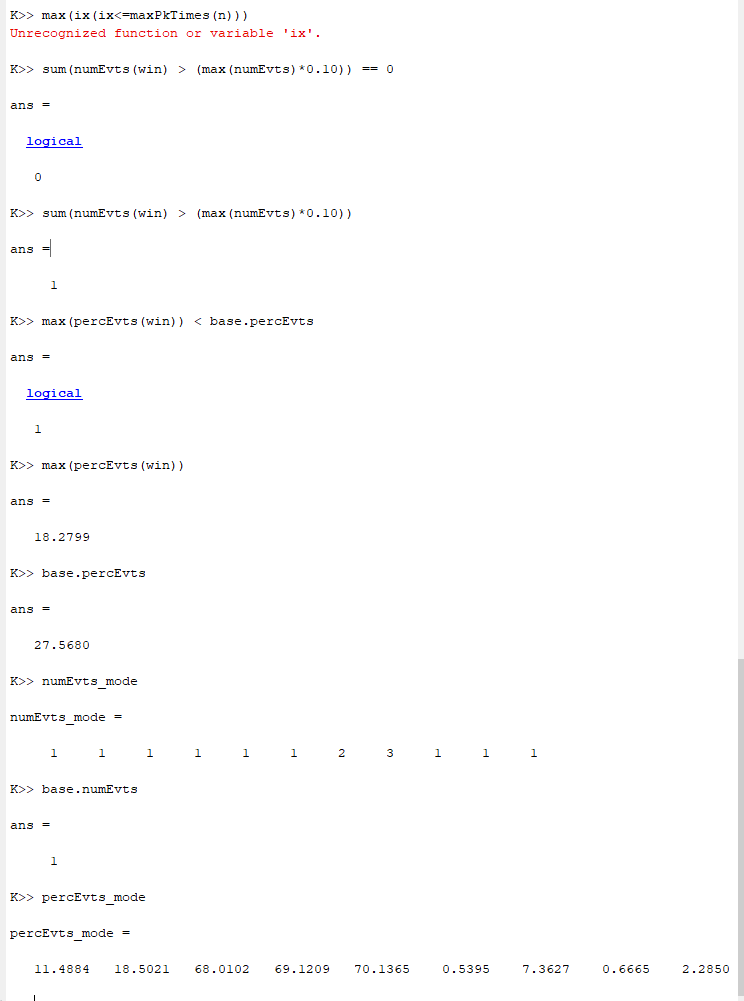

Essentially, it is calculating a high percEvts average as even in those cases where there is one event detected, percEvts can be quite high. See the 68, 69, 70 etc above

This is wrongly not detecting bursts that should be considered bursts

For now I am removing the baseline tests from the program and continuing juust to get it working.

Debugging now with breakpoint here:

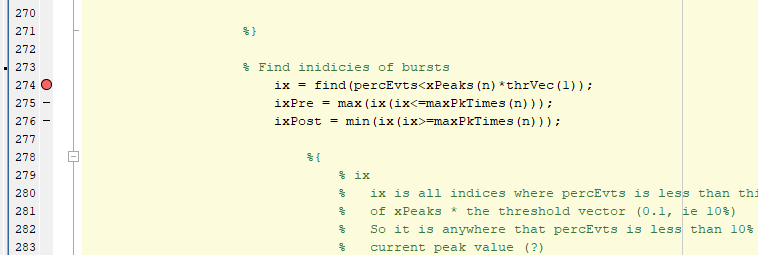

[bursts, bursStats] = CdetectBurst(out,  spRes, tRes, outDir)

"""

In this section of detectBursts:

        twindow = 1/tres;

        clear enumEvts

        j=1;

        for i=1:twindow:length(burstStats.numEvts{jj})-twindow

            enumEvts(j) = sum(burstStats.numEvts{jj}(i:i+twindow));

            j=j+1;

        end

you seem to be collecting number of events per second. However with a frame rate that does not result in an integer twindow it repeatedly throws the error: 

        "Warning: Integer operands are required for colon operator when used as index"

as expected. Is this intentional? Why not just keep number of events per frame, plot, then modify x axis to represent seconds

I guess it works its just messy.. repress error output? use floor? 

For first second we want to sum everything from frame 1 to frame 2.7 .. ie 

"""

I have changed this to 

    ceil(i) : floor(i+twindow) 

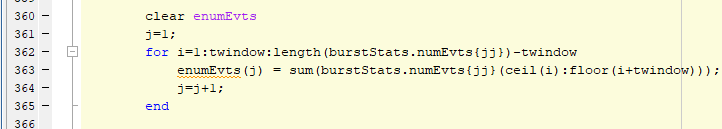

Plotting percEvts


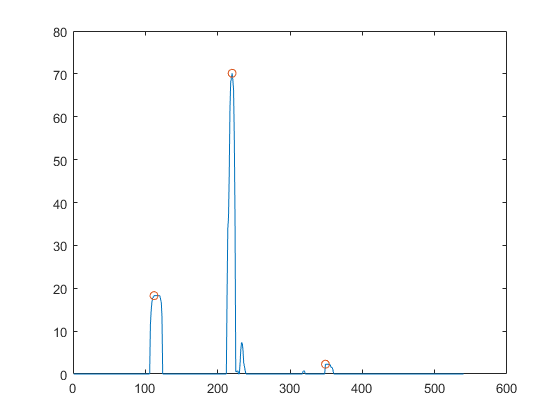

Plotting num events


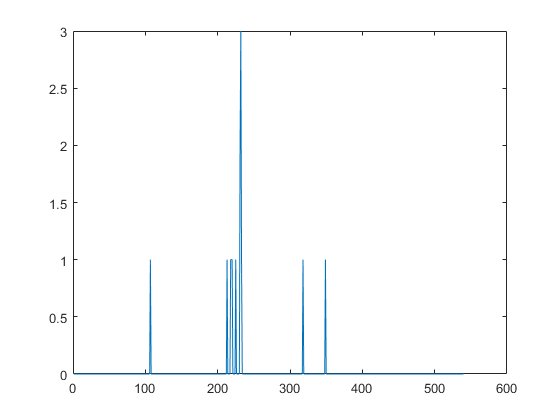

_____BASELINES_____
Baseline Number of Events:
     1

Baseline percEvents:
   27.5680

n is
     1

window is
  Columns 1 through 15

    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106

  Columns 16 through 26

   107   108   109   110   111   112   113   114   115   116   117

_____xx Detected Burst xx______
bursts{jj}(n,1)
   106

n is
     2

window is
  Columns 1 through 15

   200   201   202   203   204   205   206   207   208   209   210   211   212   213   214

  Columns 16 through 26

   215   216   217   218   219   220   221   222   223   224   225

_____xx Detected Burst xx______
bursts{jj}(n,1)
   212

n is
     3

window is
  Columns 1 through 15

   329   330   331   332   333   334   335   336   337   338   339   340   341   342   343

  Columns 16 through 26

   344   345   346   347   348   349   350   351   352   353   354

_____xx Detected Burst xx______
bursts{jj}(n,1)
   348



[bursts, bursStats] = CdetectBurst(out,  spRes, tRes, outDir)

Problem above appears to be solved

I am also making the same modifications to "Area with event activity" as the same error was occuring

From:

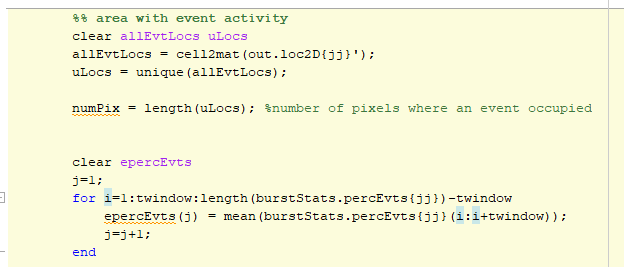

to:

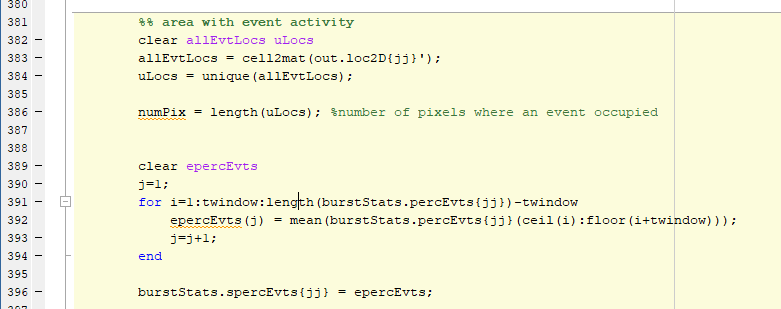

Plotting percEvts


Plotting num events


_____BASELINES_____
Baseline Number of Events:
     1

Baseline percEvents:
   27.5680

n is
     1

window is
  Columns 1 through 15

    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106

  Columns 16 through 26

   107   108   109   110   111   112   113   114   115   116   117

_____xx Detected Burst xx______
bursts{jj}(n,1)
   106

n is
     2

window is
  Columns 1 through 15

   200   201   202   203   204   205   206   207   208   209   210   211   212   213   214

  Columns 16 through 26

   215   216   217   218   219   220   221   222   223   224   225

_____xx Detected Burst xx______
bursts{jj}(n,1)
   212

n is
     3

window is
  Columns 1 through 15

   329   330   331   332   333   334   335   336   337   338   339   340   341   342   343

  Columns 16 through 26

   344   345   346   347   348   349   350   351   352   353   354

_____xx Detected Burst xx______
bursts{jj}(n,1)
   348



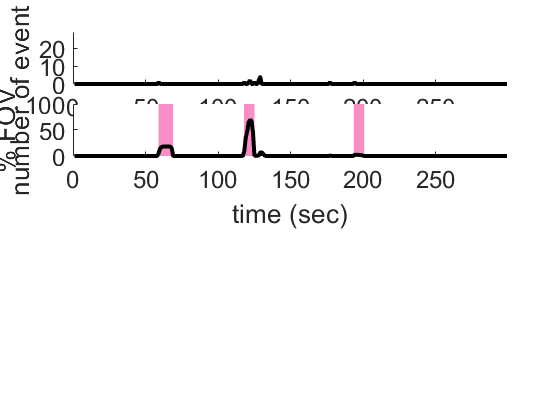

Unrecognized function or variable 'sparkleS'.

Error in CdetectBurst (line 444)
        sparkleS = sum(sparkleS,1);

[bursts, bursStats] = CdetectBurst(out,  spRes, tRes, outDir)

Issues with detecting sparkles

There will also be issue with velocity as the code is meh... may need to start sccratchy

trying run without

Plotting percEvts


Plotting num events


_____BASELINES_____
Baseline Number of Events:
     1

Baseline percEvents:
   27.5680

n is
     1

window is
  Columns 1 through 15

    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106

  Columns 16 through 26

   107   108   109   110   111   112   113   114   115   116   117

_____xx Detected Burst xx______
bursts{jj}(n,1)
   106

n is
     2

window is
  Columns 1 through 15

   200   201   202   203   204   205   206   207   208   209   210   211   212   213   214

  Columns 16 through 26

   215   216   217   218   219   220   221   222   223   224   225

_____xx Detected Burst xx______
bursts{jj}(n,1)
   212

n is
     3

window is
  Columns 1 through 15

   329   330   331   332   333   334   335   336   337   338   339   340   341   342   343

  Columns 16 through 26

   344   345   346   347   348   349   350   351   352   353   354

_____xx Detected Burst xx______
bursts{jj}(n,1)
   348



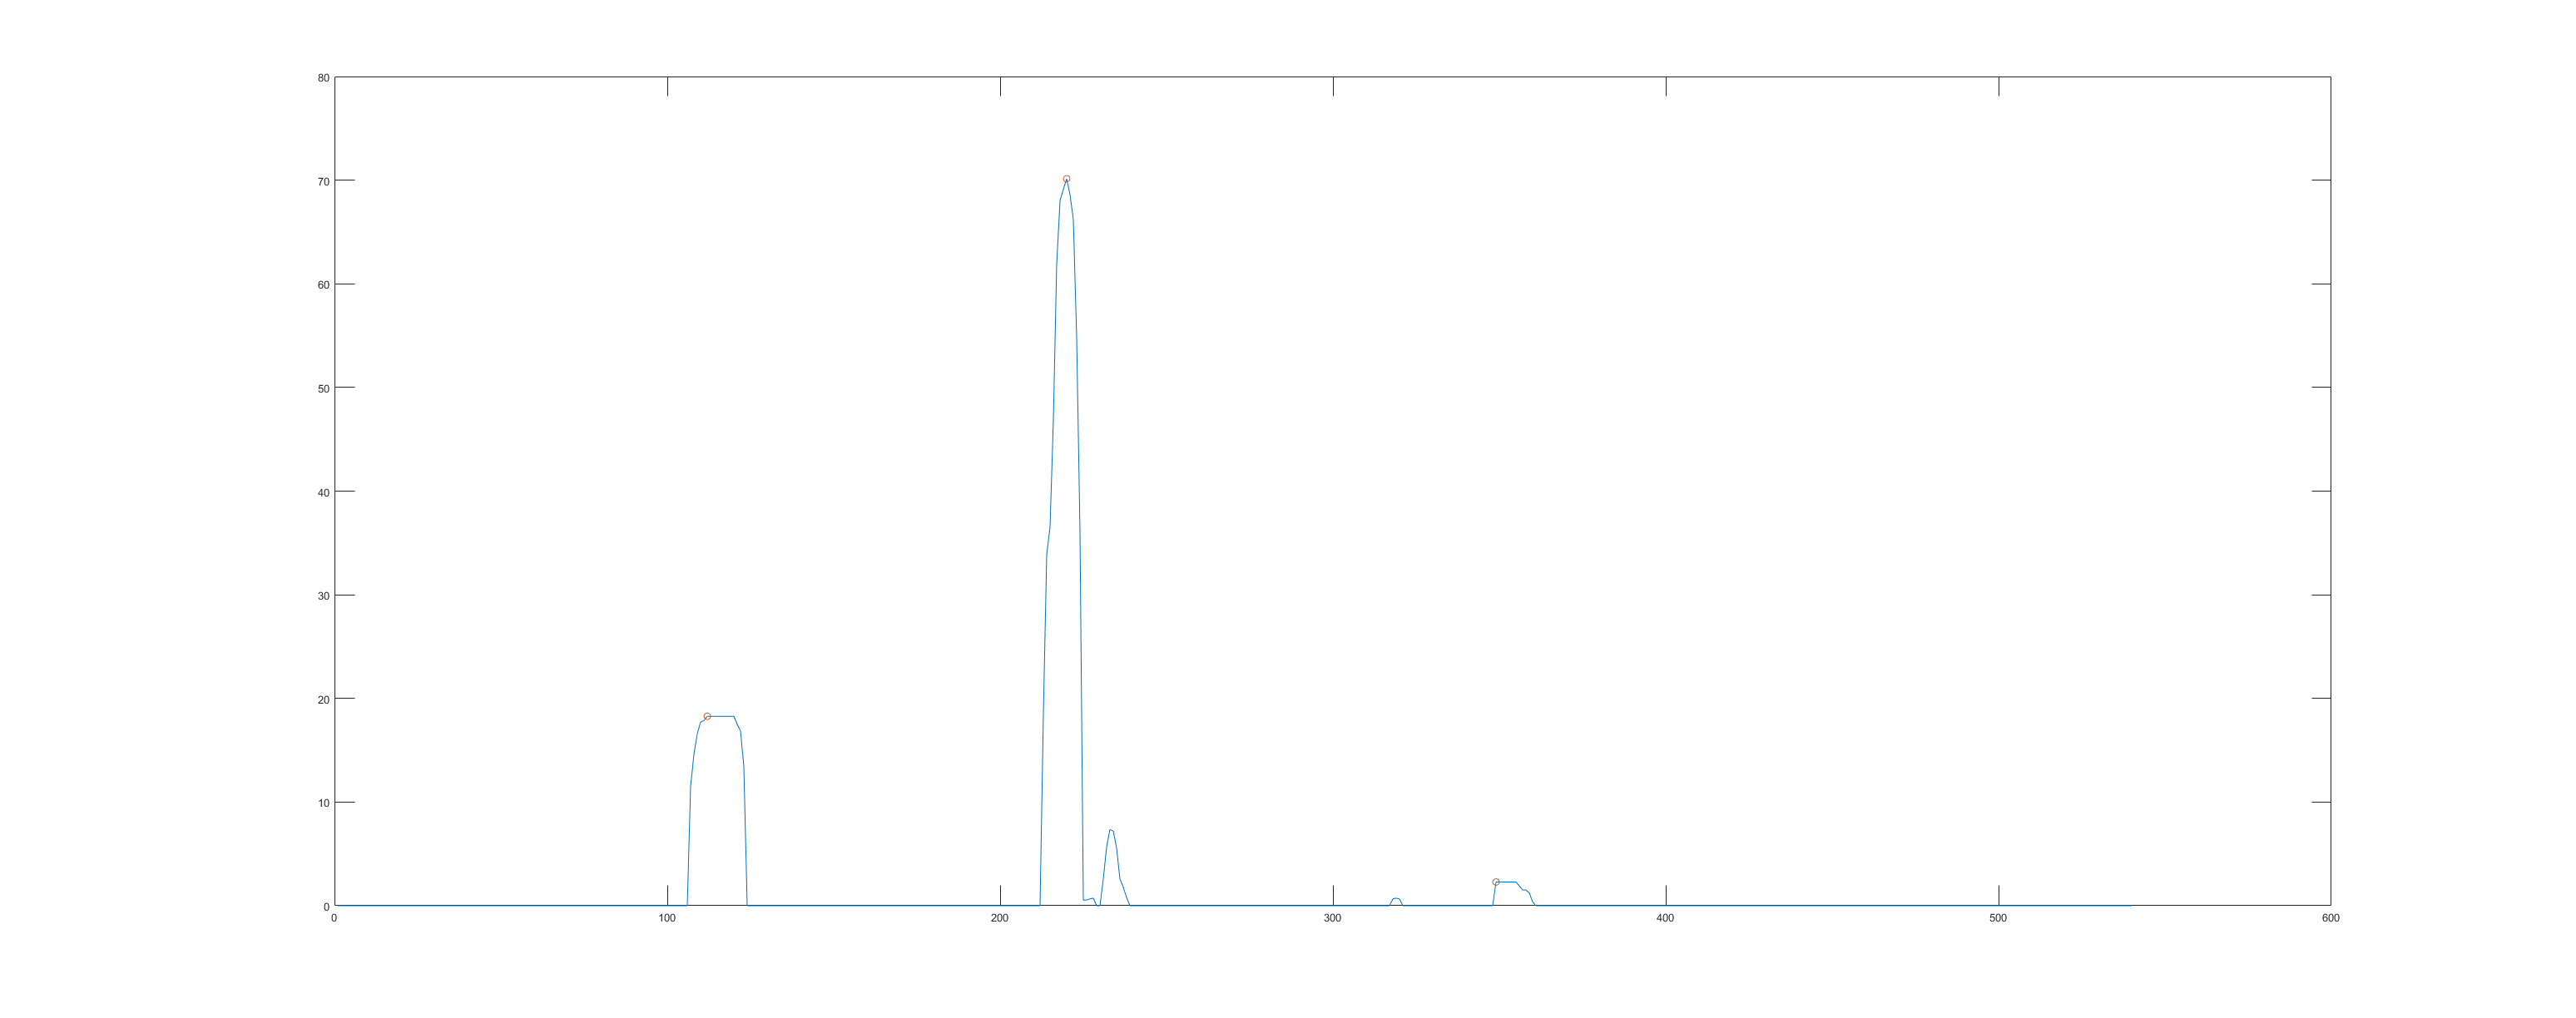

Plotting percEvts


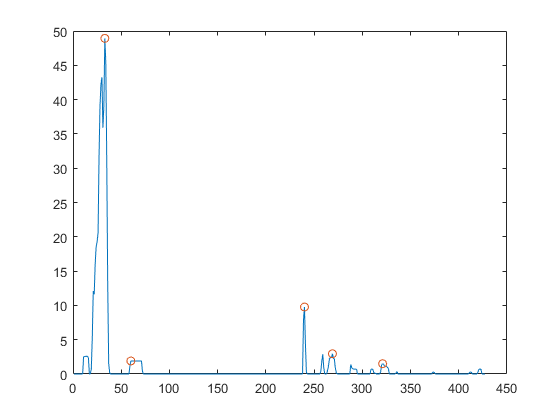

Plotting num events


_____BASELINES_____
Baseline Number of Events:
     1

Baseline percEvents:
    8.8692

n is
     1

window is
  Columns 1 through 15

    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27

  Columns 16 through 26

    28    29    30    31    32    33    34    35    36    37    38

_____xx Detected Burst xx______
bursts{jj}(n,1)
    19

n is
     2

window is
  Columns 1 through 15

    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54

  Columns 16 through 26

    55    56    57    58    59    60    61    62    63    64    65

_____xx Detected Burst xx______
bursts{jj}(n,1)
    58

n is
     3

window is
  Columns 1 through 15

   220   221   222   223   224   225   226   227   228   229   230   231   232   233   234

  Columns 16 through 26

   235   236   237   238   239   240   241   242   243   244   245

_____xx Detected Burst xx______
bursts{jj}(n,1)
   238

n is
     4

window is
  Columns 1 through 15

 

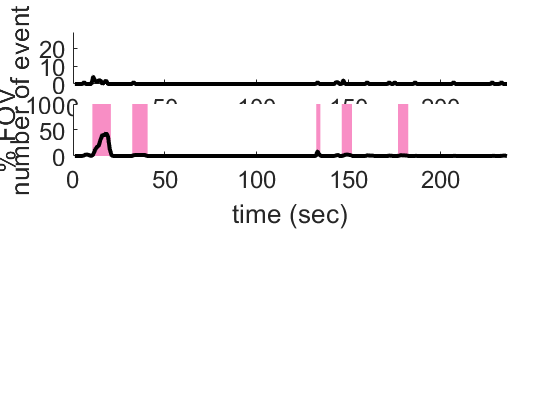

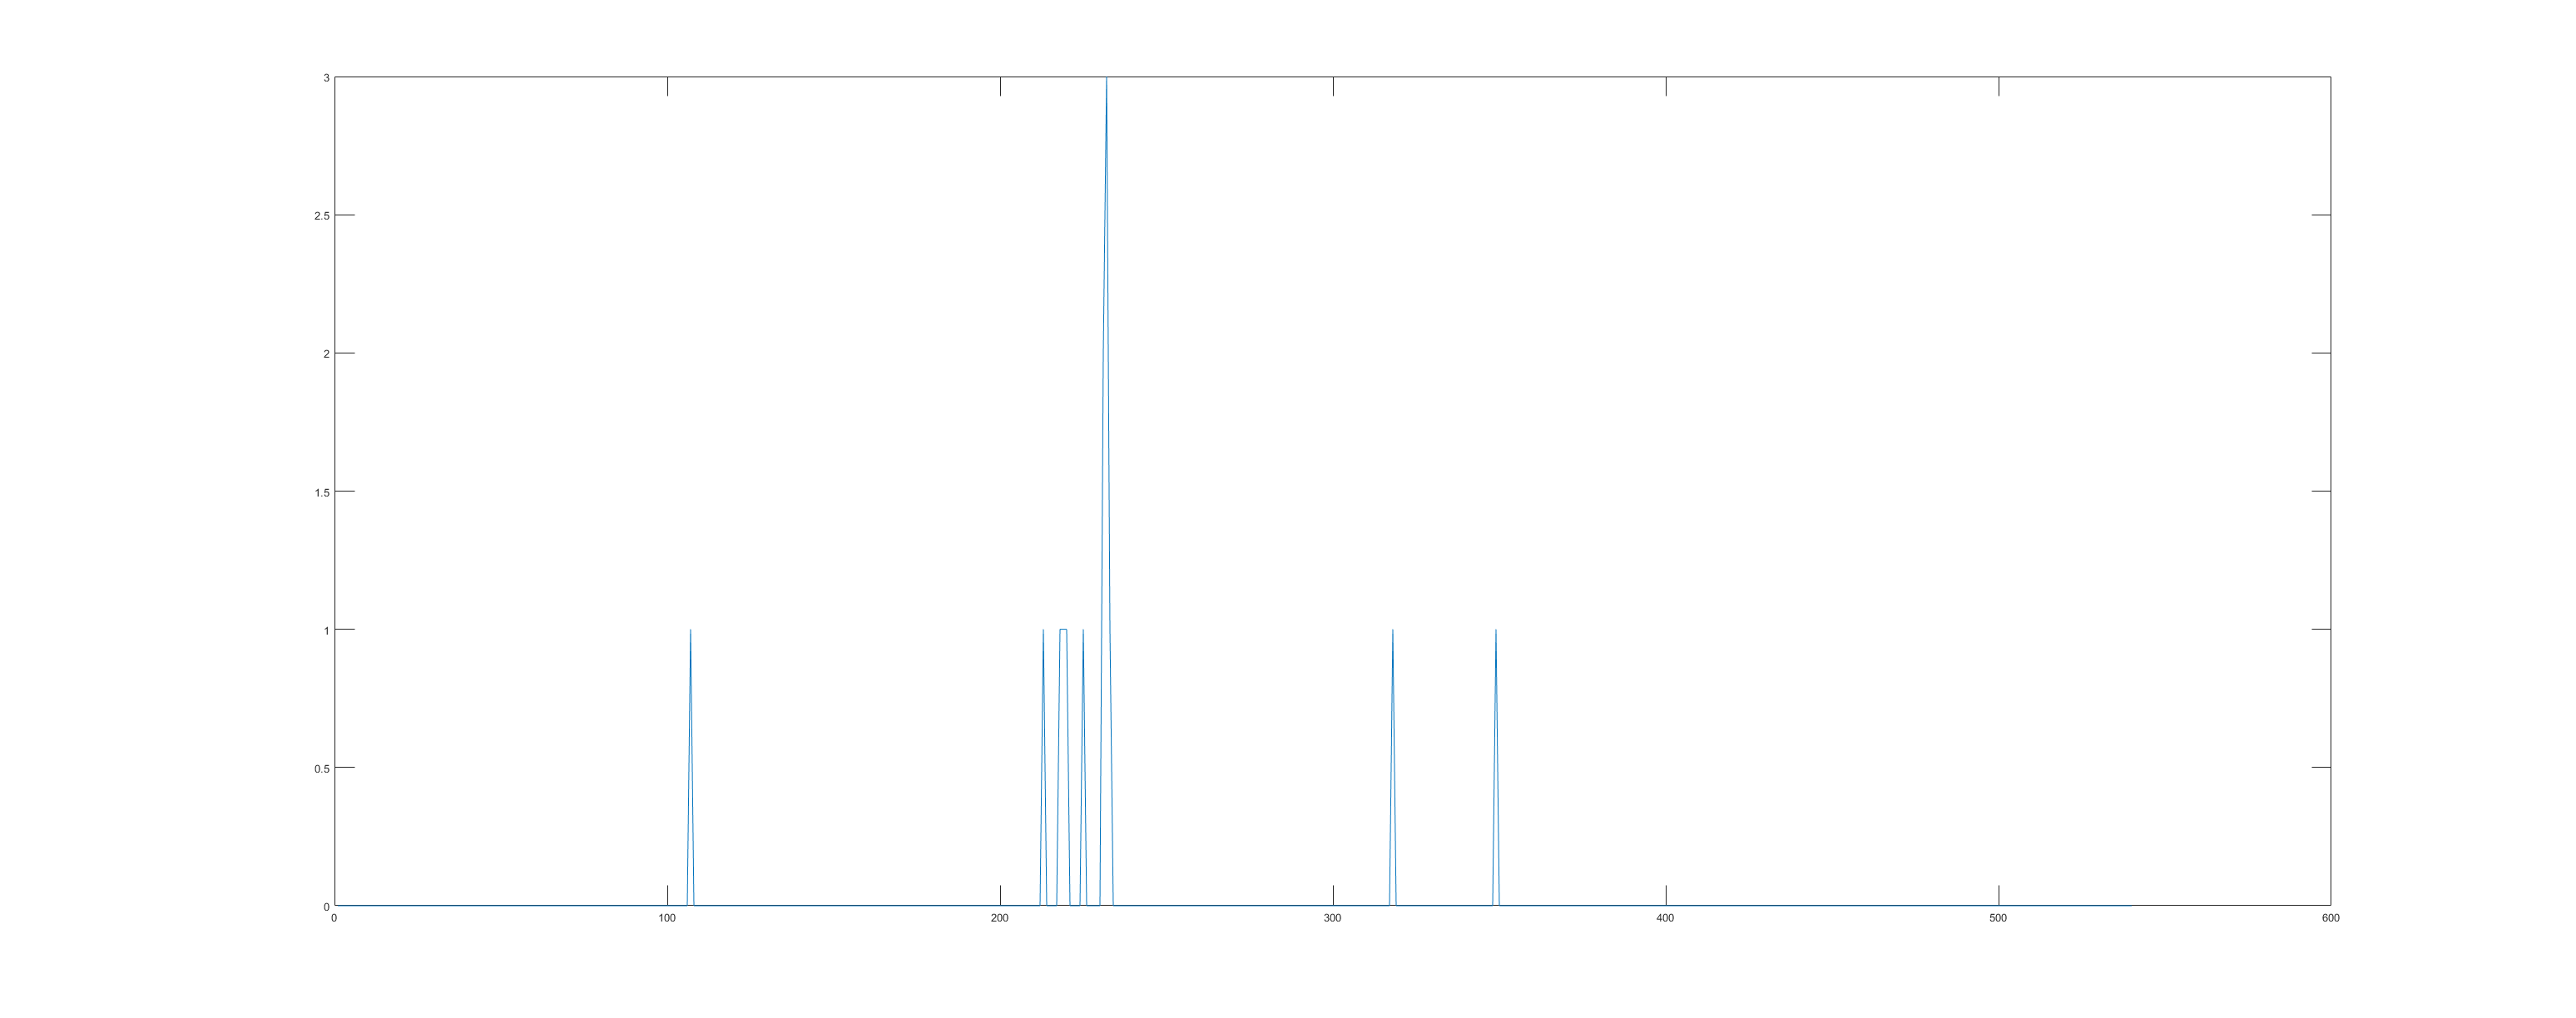

Plotting percEvts


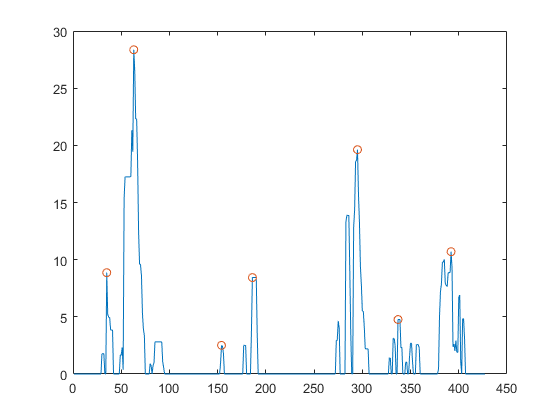

Plotting num events


_____BASELINES_____
Baseline Number of Events:
     1

Baseline percEvents:
    6.1946

n is
     1

window is
  Columns 1 through 15

    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29

  Columns 16 through 26

    30    31    32    33    34    35    36    37    38    39    40

_____xx Detected Burst xx______
bursts{jj}(n,1)
    34

n is
     2

window is
  Columns 1 through 15

    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57

  Columns 16 through 26

    58    59    60    61    62    63    64    65    66    67    68

_____xx Detected Burst xx______
bursts{jj}(n,1)
    52

n is
     3

window is
  Columns 1 through 15

   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148

  Columns 16 through 26

   149   150   151   152   153   154   155   156   157   158   159

_____xx Detected Burst xx______
bursts{jj}(n,1)
   152

n is
     4

window is
  Columns 1 through 15

 

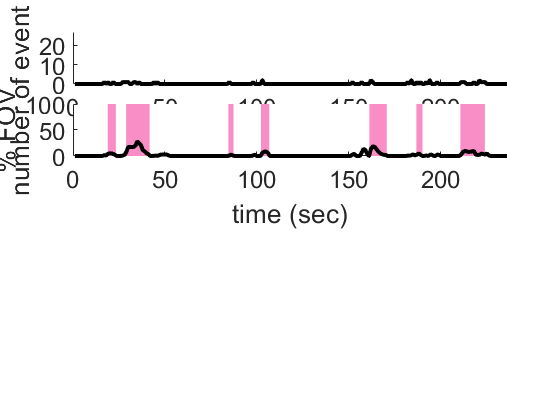

Plotting percEvts


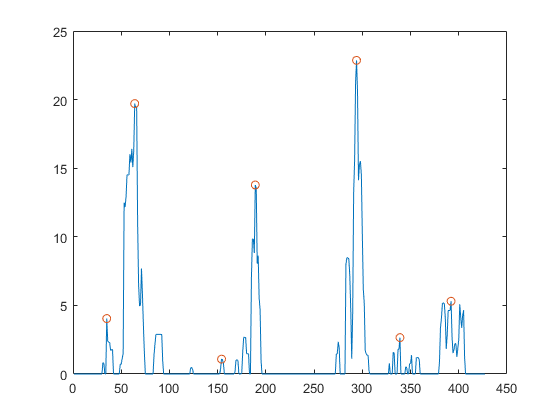

Plotting num events


_____BASELINES_____
Baseline Number of Events:
     1

Baseline percEvents:
    5.6582

n is
     1

window is
  Columns 1 through 15

    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29

  Columns 16 through 26

    30    31    32    33    34    35    36    37    38    39    40

_____xx Detected Burst xx______
bursts{jj}(n,1)
    34

n is
     2

window is
  Columns 1 through 15

    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58

  Columns 16 through 26

    59    60    61    62    63    64    65    66    67    68    69

_____xx Detected Burst xx______
bursts{jj}(n,1)
    52

n is
     3

window is
  Columns 1 through 15

   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148

  Columns 16 through 26

   149   150   151   152   153   154   155   156   157   158   159

_____xx Detected Burst xx______
bursts{jj}(n,1)
   152

n is
     4

window is
  Columns 1 through 15

 

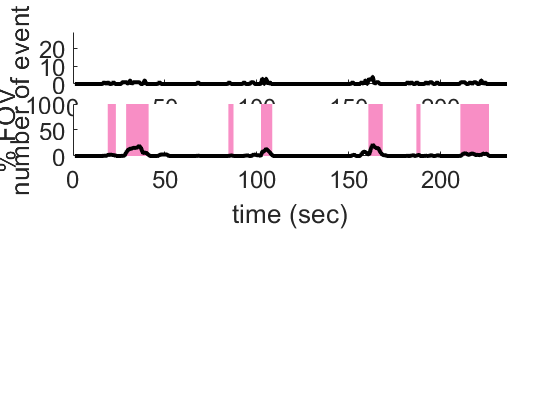

Plotting percEvts


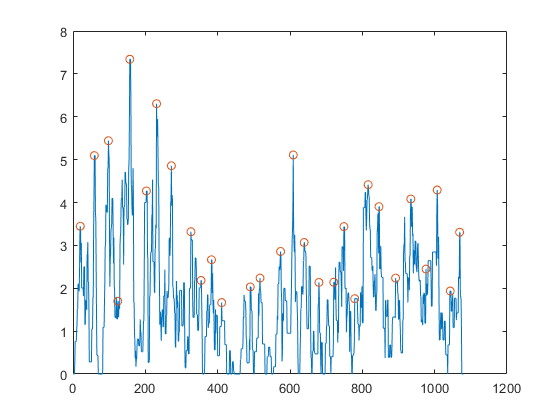

Plotting num events


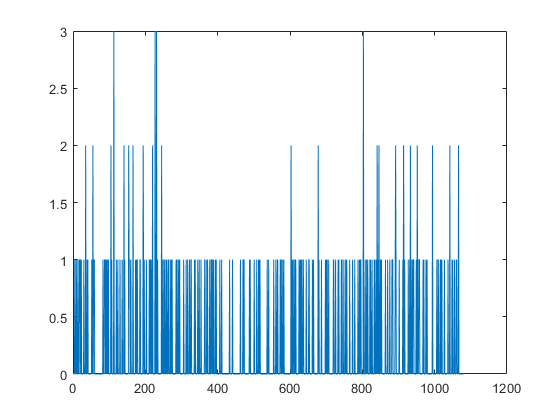

_____BASELINES_____
Baseline Number of Events:
     1

Baseline percEvents:
    2.1376

n is
     1

window is
  Columns 1 through 15

     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14

  Columns 16 through 26

    15    16    17    18    19    20    21    22    23    24    25



Array indices must be positive integers or logical values.

Error in CdetectBurst (line 252)
                        if sum(numEvts(win) > (max(numEvts)*0.10)) == 0

[bursts, bursStats] = CdetectBurst(out,  spRes, tRes, outDir)